# FillBetweenAreaCurve

This chart lets you shade the area between 2 line plots. In this example, we create a chart that shades the area between sin-x and cos-x curves

x = linspace(0, 4 * pi, 100);
y_sinx = sin(x);
y_cosx = cos(x);

## Create a Basic Chart

Let us start by creating a basic chart. Let us plot sin(x) and cos(x) on a chart and shade the area between these 2 curves.

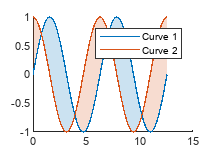

areaCurve = fillBetweenAreaCurve(x, y_sinx, y_cosx);

### Color Scheme of the Basic Chart

By default, we shade the area between 2 plots using 2 different colors. The shading color depends on the the line with the higher value. You can see that in the chart above, the all areas under the blue-colored line are shaded with light blue and vice versa. We can also change the color of a line, by default the shaded area's color will change

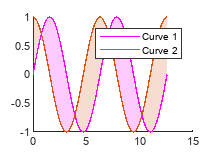

areaCurveLineColor = fillBetweenAreaCurve(x, y_sinx, y_cosx);
areaCurveLineColor.Line1Color = 'm';

## Selective Shading

The condition property is be very helpful if you want to engage in selective shading of the graph depending on certain values of x, y1 and y2. For instance, if you want to shade the same color for all value of x. You can create a condition that returns true always.

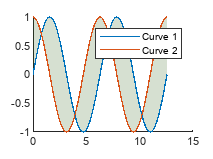

areaCurveColor = fillBetweenAreaCurve(x, y_sinx, y_cosx, [0.2 0.4 0.1], 'Condition', @(x, y1, y2)true(1, numel(x)), "ShadeInverse", false);

Note that the ShadeInverse property indicates if you would like to shade the parts of chart that are not satisfied by the Condition property. In fact any Inverse-* property indicates properties of the shaded area not satisfied by Condition.

All the areas that satisfy the condition are colored using FaceColor property. Rest of the areas are shaded using 'InverseFaceColor' property. We can change these properties, after declaring the chart

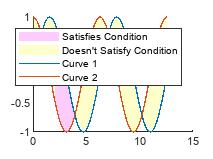

areaCurveCondition = fillBetweenAreaCurve(x, y_sinx, y_cosx, 'Condition',   @(x, y1, y2) x > 2 & x < 4);
areaCurveCondition.FaceColor = 'm';
areaCurveCondition.InverseFaceColor = 'y';

It could be possible that user only requires the shaded area to be the one that satisfies the condition. In this you can set the Shade Inverse = false

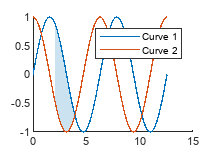

areaCurveCondition2 = fillBetweenAreaCurve(x, y_sinx, y_cosx, 'Condition',   @(x, y1, y2) x > 2 & x < 4);
areaCurveCondition2.ShadeInverse = false;

## Label Axes and Title of graph

We can also add special arguments to decorate the graph. For instance we can add title, labels of x-axis, y-axis and a legend

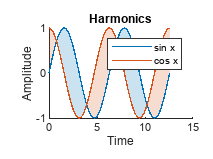

areaCurveLabel = fillBetweenAreaCurve(x, y_sinx, y_cosx, ...
    "Label1", "sin x", "Label2", "cos x", ...
    "XLabel", "Time", "YLabel", "Amplitude", "Title", "Harmonics");

We can also add Line specific properties like LineWidth, Color as key-value pairs in our arguments. In the example, we set the Color, LineWidth and LineStyle properties

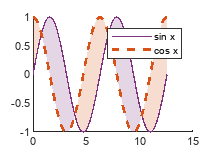

areaCurveLine1 = fillBetweenAreaCurve(x, y_sinx, y_cosx, ...
    "Label1", "sin x", "Label2", "cos x", ...
    "Line1Color", [0.5 0.2 0.5], "Line2LineWidth", 2 , "Line2LineStyle", "--" );

The chart also supports composite boolean functions such as the one's specified in xFilter. In this case, which only shade values of x that lies between 2 and 10 and y1 <= y2

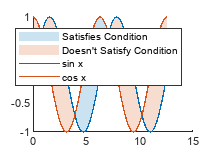

c2 = fillBetweenAreaCurve(x, y_sinx, y_cosx, ...
    "Label1", "sin x", "Label2", "cos x", ...
    "Condition", @xFilter);

## Manual Triangulation

Currently, we optimize the construction of the chart by supporting manual triangulation before passing vertices data to patch. This ensures pacth can focus on shading the triangles and not calculating the triangle vertices. However, we can pass the vertices directly to patch object without calculating triangle vertices by setting OptimizePerformance = false

areaCurveOptimized = fillBetweenAreaCurve(x, y_sinx, y_cosx, "OptimizePerformance", false);

function result = xFilter(x, y1, y2)
    result = x >= 2 & x < 10 & y1 <= y2;
end